close all; 
clear all; 
clc; 
L_num =  0.48; %- length of gyroscope axle
L2_num = 0.195; %- length of rotating axle
d1_num = 0.128 %- length from A to start of big disc (B)

d1_num = 0.1280

d2_num = 0.2175;  %- length from A to start of counterweight
t1_num = 0.0221;  %- thickness of disc
t2_num = 0.0313; %- thickness of counterweight
r1_num = 0.254/2;  %- radius of big disc
r2_num = 0.07/2;% - radius of counterweight
r3_num = 12.1/2/1000;  %- radius of gyroscope axle
r4_num = 12.1/2/1000; % - radius of rotating axle

%Gyroscope Axel - this is in frame 2
[zg,yg,xg] = cylinder(r3_num,100)

zg =     0.0060    0.0060    0.0060    0.0059    0.0059    0.0058    0.0056    0.0055    0.0053    0.0051    0.0049    0.0047    0.0044    0.0041    0.0039    0.0036    0.0032    0.0029    0.0026    0.0022    0.0019    0.0015    0.0011    0.0008    0.0004    0.0000   -0.0004   -0.0008   -0.0011   -0.0015   -0.0019   -0.0022   -0.0026   -0.0029   -0.0032   -0.0036   -0.0039   -0.0041   -0.0044   -0.0047   -0.0049   -0.0051   -0.0053   -0.0055   -0.0056   -0.0058   -0.0059   -0.0059   -0.0060   -0.0060
    0.0060    0.0060    0.0060    0.0059    0.0059    0.0058    0.0056    0.0055    0.0053    0.0051    0.0049    0.0047    0.0044    0.0041    0.0039    0.0036    0.0032    0.0029    0.0026    0.0022    0.0019    0.0015    0.0011    0.0008    0.0004    0.0000   -0.0004   -0.0008   -0.0011   -0.0015   -0.0019   -0.0022   -0.0026   -0.0029   -0.0032   -0.0036   -0.0039   -0.0041   -0.0044   -0.0047   -0.0049   -0.0051   -0.0053   -0.0055   -0.0056   -0.0058   -0.0059   -0.0059   -0.0060   -

yg =          0    0.0004    0.0008    0.0011    0.0015    0.0019    0.0022    0.0026    0.0029    0.0032    0.0036    0.0039    0.0041    0.0044    0.0047    0.0049    0.0051    0.0053    0.0055    0.0056    0.0058    0.0059    0.0059    0.0060    0.0060    0.0060    0.0060    0.0060    0.0059    0.0059    0.0058    0.0056    0.0055    0.0053    0.0051    0.0049    0.0047    0.0044    0.0041    0.0039    0.0036    0.0032    0.0029    0.0026    0.0022    0.0019    0.0015    0.0011    0.0008    0.0004
         0    0.0004    0.0008    0.0011    0.0015    0.0019    0.0022    0.0026    0.0029    0.0032    0.0036    0.0039    0.0041    0.0044    0.0047    0.0049    0.0051    0.0053    0.0055    0.0056    0.0058    0.0059    0.0059    0.0060    0.0060    0.0060    0.0060    0.0060    0.0059    0.0059    0.0058    0.0056    0.0055    0.0053    0.0051    0.0049    0.0047    0.0044    0.0041    0.0039    0.0036    0.0032    0.0029    0.0026    0.0022    0.0019    0.0015    0.0011    0.0008    

xg =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


xg = xg*L_num - (L_num-d1_num); 


%Gyroscope CounterWeight - this is in frame 2
[zc, yc, xc] = cylinder(r2_num,100)

zc =     0.0350    0.0349    0.0347    0.0344    0.0339    0.0333    0.0325    0.0317    0.0307    0.0296    0.0283    0.0270    0.0255    0.0240    0.0223    0.0206    0.0188    0.0169    0.0149    0.0129    0.0108    0.0087    0.0066    0.0044    0.0022    0.0000   -0.0022   -0.0044   -0.0066   -0.0087   -0.0108   -0.0129   -0.0149   -0.0169   -0.0188   -0.0206   -0.0223   -0.0240   -0.0255   -0.0270   -0.0283   -0.0296   -0.0307   -0.0317   -0.0325   -0.0333   -0.0339   -0.0344   -0.0347   -0.0349
    0.0350    0.0349    0.0347    0.0344    0.0339    0.0333    0.0325    0.0317    0.0307    0.0296    0.0283    0.0270    0.0255    0.0240    0.0223    0.0206    0.0188    0.0169    0.0149    0.0129    0.0108    0.0087    0.0066    0.0044    0.0022    0.0000   -0.0022   -0.0044   -0.0066   -0.0087   -0.0108   -0.0129   -0.0149   -0.0169   -0.0188   -0.0206   -0.0223   -0.0240   -0.0255   -0.0270   -0.0283   -0.0296   -0.0307   -0.0317   -0.0325   -0.0333   -0.0339   -0.0344   -0.0347   -

yc =          0    0.0022    0.0044    0.0066    0.0087    0.0108    0.0129    0.0149    0.0169    0.0188    0.0206    0.0223    0.0240    0.0255    0.0270    0.0283    0.0296    0.0307    0.0317    0.0325    0.0333    0.0339    0.0344    0.0347    0.0349    0.0350    0.0349    0.0347    0.0344    0.0339    0.0333    0.0325    0.0317    0.0307    0.0296    0.0283    0.0270    0.0255    0.0240    0.0223    0.0206    0.0188    0.0169    0.0149    0.0129    0.0108    0.0087    0.0066    0.0044    0.0022
         0    0.0022    0.0044    0.0066    0.0087    0.0108    0.0129    0.0149    0.0169    0.0188    0.0206    0.0223    0.0240    0.0255    0.0270    0.0283    0.0296    0.0307    0.0317    0.0325    0.0333    0.0339    0.0344    0.0347    0.0349    0.0350    0.0349    0.0347    0.0344    0.0339    0.0333    0.0325    0.0317    0.0307    0.0296    0.0283    0.0270    0.0255    0.0240    0.0223    0.0206    0.0188    0.0169    0.0149    0.0129    0.0108    0.0087    0.0066    0.0044    

xc =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


xc = xc* t2_num - t2_num - d2_num;

%Rotating Disk
[zd, yd, xd] = cylinder(r1_num, 100)

zd =     0.1270    0.1267    0.1260    0.1248    0.1230    0.1208    0.1181    0.1149    0.1113    0.1072    0.1027    0.0979    0.0926    0.0869    0.0810    0.0746    0.0681    0.0612    0.0541    0.0468    0.0392    0.0316    0.0238    0.0159    0.0080    0.0000   -0.0080   -0.0159   -0.0238   -0.0316   -0.0392   -0.0468   -0.0541   -0.0612   -0.0681   -0.0746   -0.0810   -0.0869   -0.0926   -0.0979   -0.1027   -0.1072   -0.1113   -0.1149   -0.1181   -0.1208   -0.1230   -0.1248   -0.1260   -0.1267
    0.1270    0.1267    0.1260    0.1248    0.1230    0.1208    0.1181    0.1149    0.1113    0.1072    0.1027    0.0979    0.0926    0.0869    0.0810    0.0746    0.0681    0.0612    0.0541    0.0468    0.0392    0.0316    0.0238    0.0159    0.0080    0.0000   -0.0080   -0.0159   -0.0238   -0.0316   -0.0392   -0.0468   -0.0541   -0.0612   -0.0681   -0.0746   -0.0810   -0.0869   -0.0926   -0.0979   -0.1027   -0.1072   -0.1113   -0.1149   -0.1181   -0.1208   -0.1230   -0.1248   -0.1260   -

yd =          0    0.0080    0.0159    0.0238    0.0316    0.0392    0.0468    0.0541    0.0612    0.0681    0.0746    0.0810    0.0869    0.0926    0.0979    0.1027    0.1072    0.1113    0.1149    0.1181    0.1208    0.1230    0.1248    0.1260    0.1267    0.1270    0.1267    0.1260    0.1248    0.1230    0.1208    0.1181    0.1149    0.1113    0.1072    0.1027    0.0979    0.0926    0.0869    0.0810    0.0746    0.0681    0.0612    0.0541    0.0468    0.0392    0.0316    0.0238    0.0159    0.0080
         0    0.0080    0.0159    0.0238    0.0316    0.0392    0.0468    0.0541    0.0612    0.0681    0.0746    0.0810    0.0869    0.0926    0.0979    0.1027    0.1072    0.1113    0.1149    0.1181    0.1208    0.1230    0.1248    0.1260    0.1267    0.1270    0.1267    0.1260    0.1248    0.1230    0.1208    0.1181    0.1149    0.1113    0.1072    0.1027    0.0979    0.0926    0.0869    0.0810    0.0746    0.0681    0.0612    0.0541    0.0468    0.0392    0.0316    0.0238    0.0159    

xd =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


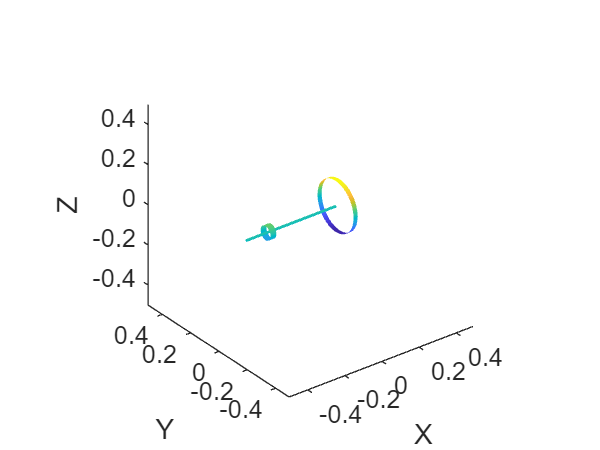

xd = xd*t1_num + d1_num; 

figure; 
hold on; 
surf(xg,yg,zg, zg, "EdgeColor","none")
surf(xc,yc,zc, zc, "EdgeColor","none")
surf(xd,yd,zd, zd, "EdgeColor","none")
axis square
view(3)
axis(1*[-0.5 0.5 -0.5 0.5 -0.5 0.5])
xlabel('X')
ylabel('Y')
zlabel('Z')